close all;
clear all;

This script reads a single CSV measurement and determines the decibel at the peak and the Q factor. For reading multiple measurments, see V2.

%Choose measurement set
set = "20thApril\"; n = 8;
%set = "8thApril\"; n = 8;
%set = "5thApril\"; n = 5;
%set = "29thApril\"; n = 6;

%Choose an antenna
%folder = "1814";
folder = "1937";
%folder = "2028";

The first part of this code reads the specified amount of measurements from a source folder and plots all in a graph.

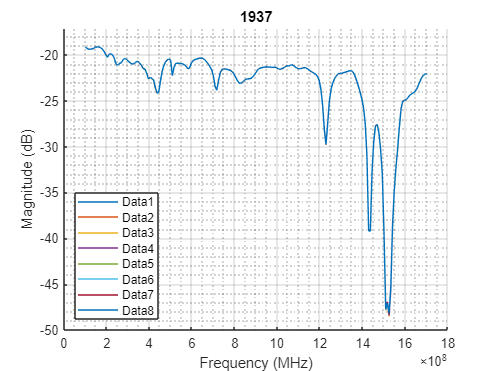

path = "C:\Users\guusb\OneDrive - Office 365 Fontys\Graduation project (Guus 2022)\TestResults\";

for ind = 1:1:n
    str = string(ind);
    filepath = append(path, set, folder,"\TRACE0",str,".CSV");
   
    data = csvread(filepath, 3, 0)';  %the arguments are at which point the data starts
    data(3,:) = [];
    
    combinationMatrix(1,:) = data(1,:); %this line could be redundant
    combinationMatrix(ind+1,:) = data(2,:);
end

%finds the extremes of the dataset to adjust the graph boundaries
ymax = max(data(2,:));
ymin = min(data(2,:));
xlim = [data(1,1) data(1,end)];
ylim = [ymin ymax];
    
figure()
hold on
for ind1 = 1:1:n
    plot(combinationMatrix(1,:), combinationMatrix(ind1+1,:));
end

axis([xlim ylim])
axis padded
grid on
grid minor;
title(folder);
xlabel("Frequency (MHz)");
ylabel("Magnitude (dB)");
hold on

%legend('show')
legend({'Data1','Data2','Data3','Data4','Data5','Data6','Data7','Data8'}, 'Location','southwest');

In this section the average respondse is determined and from that the deviation from that responds for all measurements in the set.

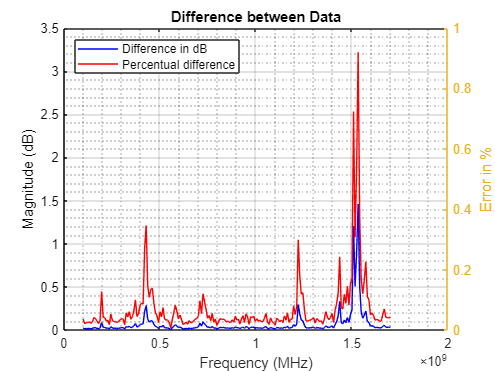

data_only = combinationMatrix(2:end,:);
avg_data = mean(data_only);

siz = size(data_only);
diff_array = zeros(siz(1),siz(2));
for i = 1:1:n
    diff_array(i,:) = abs(data_only(i,:)-avg_data);
end

err = sum(diff_array);
err_percent = rdivide(err,abs(avg_data)).*100;

figure()
plot(combinationMatrix(1,:), err(1:end),'b',combinationMatrix(1,:), err_percent(1,:),'r')
%plot(combinationMatrix(1,:), err_percent(1,:),'r');
grid on
grid minor;
title("Difference between Data");
xlabel("Frequency (MHz)");
yyaxis left
ylabel("Magnitude (dB)");
yyaxis right
ylabel("Error in %");
legend({'Difference in dB','Percentual difference'}, 'Location','northwest');